## Linear Parametrization

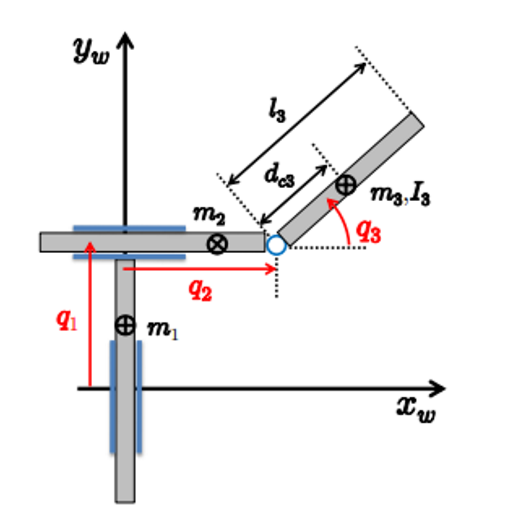

syms q1 q2 q3 dq1 dq2 dq3 m1 m2 m3 real
syms l1 l2 l3 d1 d2 d3 g0 I3 real

% Joint 1
T1 = 0.5*m1*dq1^2

$$T1 = \frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}$$


% Joint 2
x2 = q2 - d2;
y2 = q1

$$y2 = q_{1}$$

vx2 = diff(x2,q1)*dq1 + diff(x2, q2)*dq2 + diff(x2, q3)*dq3;
vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2 + diff(y2, q3)*dq3;

T2 = 0.5*m2*[vx2 vy2]*[vx2; vy2;]

$$T2 = \frac{m_{2}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{dq}}_{2}}^{2}}{2}$$


% Joint 3
x3 = q2 + d3*cos(q3);
y3 = q1 + d3*sin(q3);

vx3 = diff(x3,q1)*dq1 + diff(x3, q2)*dq2 + diff(x3, q3)*dq3;
vy3 = diff(y3, q1)*dq1 + diff(y3, q2)*dq2 + diff(y3, q3)*dq3;

T3 = 0.5*m3*[vx3 vy3]*[vx3; vy3;] + 0.5*I3*dq3^2;

% Total Kinetic Energy
T=T1+T2+T3

$$T = \frac{I_{3}\,{{\mathrm{dq}}_{3}}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,m_{2}}{2}+\frac{m_{3}\,{\left({\mathrm{dq}}_{1}+d_{3}\,{\mathrm{dq}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{dq}}_{2}-d_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M13 = diff(diff(T, dq1), dq3);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);
M23 = diff(diff(T, dq2), dq3);

M31 = diff(diff(T, dq3), dq1);
M32 = diff(diff(T, dq3), dq2);
M33 = diff(diff(T, dq3), dq3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33;];

M_simp = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M_simp);

$$\left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & d_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & -d_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ d_{3}\,m_{3}\,\cos\left(q_{3}\right) & -d_{3}\,m_{3}\,\sin\left(q_{3}\right) & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)$$

### Parametrization

ddq = [ddq1; ddq2; ddq3;];
M_para = [     a1         0        a2*cos(q3);
               0          a3      -a2*sin(q3);
          a2*cos(q3)  -a2*sin(q3)      a4;]

$$M\_para = \left(\begin{array}{ccc} a_{1} & 0 & a_{2}\,\cos\left(q_{3}\right)\\ 0 & a_{3} & -a_{2}\,\sin\left(q_{3}\right)\\ a_{2}\,\cos\left(q_{3}\right) & -a_{2}\,\sin\left(q_{3}\right) & a_{4} \end{array}\right)$$


Ya = M_para*ddq

$$Ya = \left(\begin{array}{c} a_{1}\,{\mathrm{ddq}}_{1}+a_{2}\,{\mathrm{ddq}}_{3}\,\cos\left(q_{3}\right)\\ a_{3}\,{\mathrm{ddq}}_{2}-a_{2}\,{\mathrm{ddq}}_{3}\,\sin\left(q_{3}\right)\\ a_{4}\,{\mathrm{ddq}}_{3}-a_{2}\,{\mathrm{ddq}}_{2}\,\sin\left(q_{3}\right)+a_{2}\,{\mathrm{ddq}}_{1}\,\cos\left(q_{3}\right) \end{array}\right)$$


% Dynamic symbols
dynamic_symbols = [a1, a2, a3, a4];

Y = extract_Y_v3(Ya, dynamic_symbols);

disp('Regressor Matrix Y:');

Regressor Matrix Y:


disp(Y);

$$\left(\begin{array}{cccc} {\mathrm{ddq}}_{1} & {\mathrm{ddq}}_{3}\,\cos\left(q_{3}\right) & 0 & 0\\ 0 & -{\mathrm{ddq}}_{3}\,\sin\left(q_{3}\right) & {\mathrm{ddq}}_{2} & 0\\ 0 & {\mathrm{ddq}}_{1}\,\cos\left(q_{3}\right)-{\mathrm{ddq}}_{2}\,\sin\left(q_{3}\right) & 0 & {\mathrm{ddq}}_{3} \end{array}\right)$$

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % Estrae la matrice di regressione Y da un'espressione Ya lineare
    % nei simboli elencati in dynamic_symbols.
    %
    % Ya              : espressione simbolica (ad es. M*ddq + c + G)
    % dynamic_symbols : array contenente [a1, a2, ..., aN]
    %
    % Output: Y       : matrice che, moltiplicata per [a1; a2; ...; aN],
    %                   restituisce l'originale Ya.

    % Inizializzazione
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    % Assicuriamoci di avere dynamic_symbols come array riga
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i = 1:Y_columns
        % Costruisco un array di sostituzione: tutti zeri tranne un 1
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        % Sostituisco in Ya: a_i=1, gli altri=0
        Yi = subs(Ya, dynamic_symbols, subs_array);

        % Concateno in colonna
        Y = [Y, Yi];
    end
end